m=mobiledev

m = mobiledev with properties:

                      Device: 'Galaxy A52s 5G'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0
Show all properties

m.AccelerationSensorEnabled = 1;
m.Logging = 1;

m.Logging = 0;

[a, t] = accellog(m);

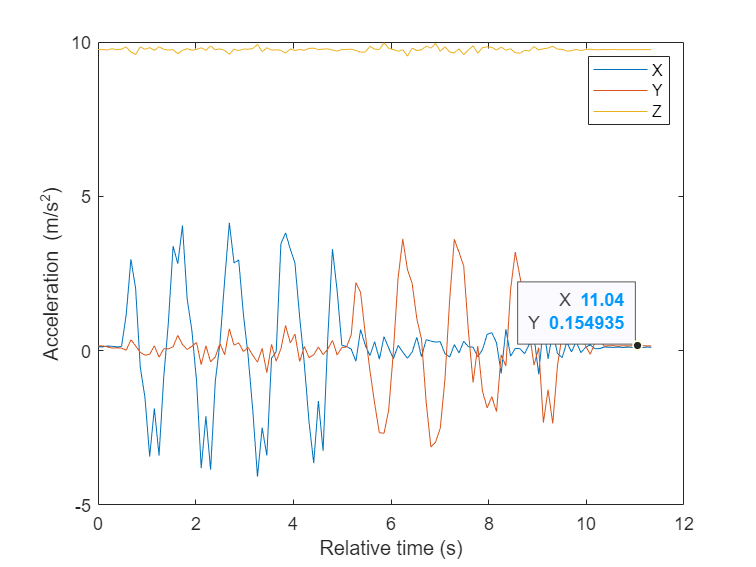

plot(t, a);
legend('X', 'Y', 'Z');
xlabel('Relative time (s)');
ylabel('Acceleration (m/s^2)');

t(end)

ans = 7.2000

length(t)

ans = 77

a(1,2)

ans = -2.1817

for i= 1:length(t)
    if i==1
        vx(i)= 0+a(i,1)*(t(end)/length(t));
        vy(i)= 0+a(i,2)*(t(end)/length(t));
    else
        vx(i)= vx(i-1)+a(i,1)*(t(end)/length(t));
        vy(i)= vy(i-1)+a(i,2)*(t(end)/length(t));
    end
end

plot(t, vx);hold

현재 플롯이 유지됨


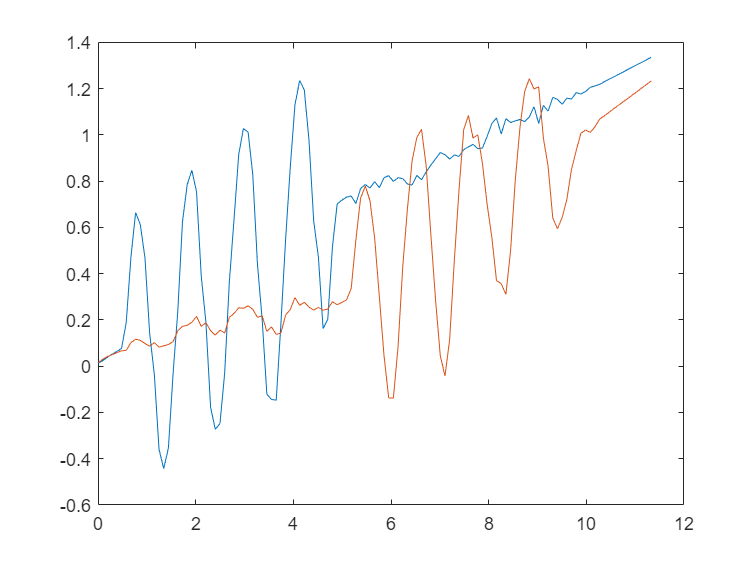

plot(t, vy);hold off

for i= 1:length(t)
    px(i)= vx(i)*(t(end)/length(t));
    py(i)= vy(i)*(t(end)/length(t));
end

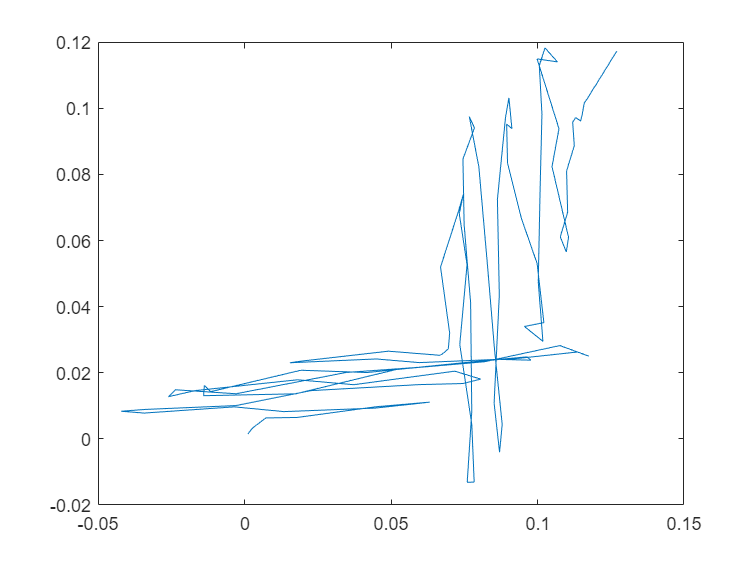

plot(px,py)

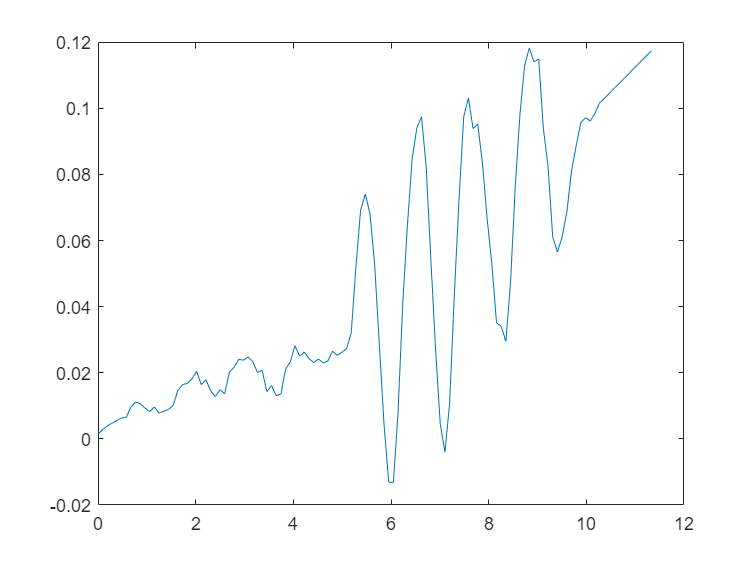

plot(t,py)

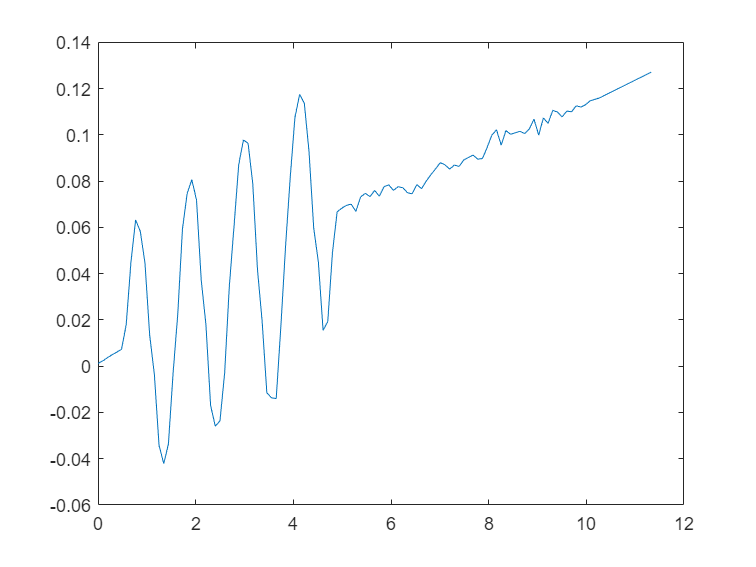

plot(t,px)



m.AccelerationSensorEnabled = 0;
% clear m;




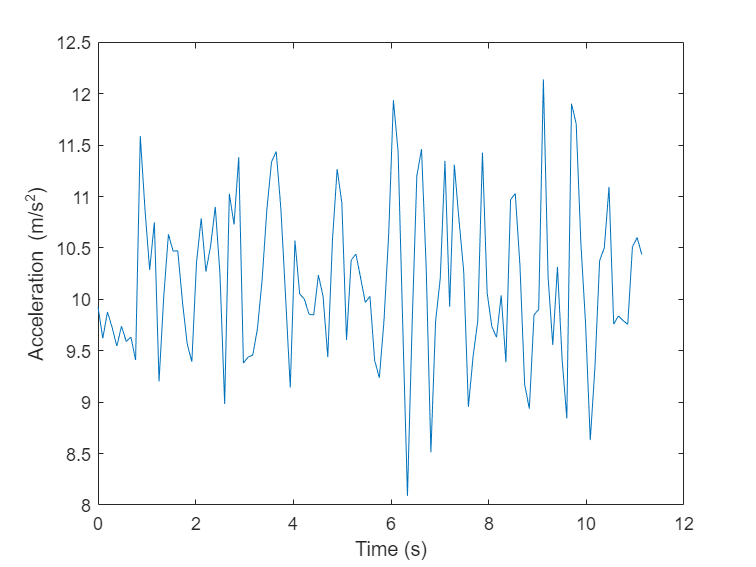

x = a(:,1);
y = a(:,2);
z = a(:,3);

% Calculate and plot magnitude.
mag = sqrt(sum(x.^2 + y.^2 + z.^2, 2));
plot(t, mag);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

m.Acceleration(1)

ans = -3.2312

 
velocity.X = cumtrapz(1/10,acceleration.X/1000*9.81);

다음 사용 중 오류가 발생함: cumtrapz
차원 인수는 인덱스 범위 내에 있는 양의 정수 스칼라여야 합니다.

volocity.Y = cumtrapz(1/10,acceleration.Y/1000*9.81);
velocity.Z = cumtrapz(1/10,acceleration.Z/1000*9.81);
position.X = trapz(1/10,velocity.X);
position.Y = trapz(1/10,velocity.Y);
position.Z = trapz(1/10,velocity.Z);